
clear all
close all
clc

% Initiate your values 
step = 0.1;
x = -5:step:5;

% Initiate basic curve
% The objective is to achieve a curve as close to it as possible
y = 2*x.^2 + 4*x -5

y =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800




hold on

% Add noise to the curve. 
y_noisy = y + 70*(rand(1,length(x))-0.5);
plot(x,y_noisy)

% Median filter, size 5
n = 13

n = 13

offset = 6 % offset must be n/2 (integer division)

offset = 6


% Loop through values of x minus first and last values
for i = offset: length(x)-2*offset
   
    for j = 1: 2*offset+1
    % Create segment of length 2*offset+1 of values y(x=i within segment)
    segment(j) = y(i-offset + j)

    end

    Med = median(segment) % Find the median of the segment
    theMean = mean(segment) % Find the mean of the segment
    YMedFiltered(i) = Med  % Make an array of the median values
    YMeanFiltered(i) = theMean % Make an array of the mean values

end

segment = 25

segment =    25.0000   23.4200


segment =    25.0000   23.4200   21.8800


segment =    25.0000   23.4200   21.8800   20.3800


segment =    25.0000   23.4200   21.8800   20.3800   18.9200


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200


segment =    25.0000   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


Med = 16.1200

theMean = 16.4000

YMedFiltered =          0         0         0         0         0   16.1200


YMeanFiltered =          0         0         0         0         0   16.4000


segment =    23.4200   23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800


segment =    23.4200   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


Med = 14.7800

theMean = 15.0600

YMedFiltered =          0         0         0         0         0   16.1200   14.7800


YMeanFiltered =          0         0         0         0         0   16.4000   15.0600


segment =    21.8800   21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800


segment =    21.8800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


Med = 13.4800

theMean = 13.7600

YMedFiltered =          0         0         0         0         0   16.1200   14.7800   13.4800


YMeanFiltered =          0         0         0         0         0   16.4000   15.0600   13.7600


segment =    20.3800   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment =    20.3800   18.9200   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment =    20.3800   18.9200   17.5000   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment =    20.3800   18.9200   17.5000   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment =    20.3800   18.9200   17.5000   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200


segment = 1×13
   20.3800   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


Med = 12.2200

theMean = 12.5000

YMedFiltered = 1×9
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200


YMeanFiltered = 1×9
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000


segment = 1×13
   18.9200   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000


segment = 1×13
   18.9200   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


Med = 11

theMean = 11.2800

YMedFiltered = 1×10
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000


YMeanFiltered = 1×10
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800


segment = 1×13
   17.5000   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200


segment = 1×13
   17.5000   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


Med = 9.8200

theMean = 10.1000

YMedFiltered = 1×11
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200


YMeanFiltered = 1×11
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000


segment = 1×13
   16.1200   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800


segment = 1×13
   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


Med = 8.6800

theMean = 8.9600

YMedFiltered = 1×12
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800


YMeanFiltered = 1×12
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600


segment = 1×13
   14.7800   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800


segment = 1×13
   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


Med = 7.5800

theMean = 7.8600

YMedFiltered = 1×13
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800


YMeanFiltered = 1×13
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600


segment = 1×13
   13.4800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200


segment = 1×13
   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


Med = 6.5200

theMean = 6.8000

YMedFiltered = 1×14
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200


YMeanFiltered = 1×14
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000


segment = 1×13
   12.2200   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000


segment = 1×13
   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


Med = 5.5000

theMean = 5.7800

YMedFiltered = 1×15
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000


YMeanFiltered = 1×15
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800


segment = 1×13
   11.0000   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200


segment = 1×13
   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


Med = 4.5200

theMean = 4.8000

YMedFiltered = 1×16
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200


YMeanFiltered = 1×16
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000


segment = 1×13
    9.8200    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200


segment = 1×13
    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


Med = 3.5800

theMean = 3.8600

YMedFiltered = 1×17
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800


YMeanFiltered = 1×17
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600


segment = 1×13
    8.6800    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200


segment = 1×13
    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


Med = 2.6800

theMean = 2.9600

YMedFiltered = 1×18
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800


YMeanFiltered = 1×18
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600


segment = 1×13
    7.5800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800


segment = 1×13
    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


Med = 1.8200

theMean = 2.1000

YMedFiltered = 1×19
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200


YMeanFiltered = 1×19
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000


segment = 1×13
    6.5200    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000


segment = 1×13
    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


Med = 1

theMean = 1.2800

YMedFiltered = 1×20
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000


YMeanFiltered = 1×20
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800


segment = 1×13
    5.5000    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800


segment = 1×13
    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


Med = 0.2200

theMean = 0.5000

YMedFiltered = 1×21
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200


YMeanFiltered = 1×21
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000


segment = 1×13
    4.5200    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200


segment = 1×13
    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


Med = -0.5200

theMean = -0.2400

YMedFiltered = 1×22
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200


YMeanFiltered = 1×22
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400


segment = 1×13
    3.5800    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200


segment = 1×13
    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


Med = -1.2200

theMean = -0.9400

YMedFiltered = 1×23
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200


YMeanFiltered = 1×23
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400


segment = 1×13
    2.6800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800


segment = 1×13
    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


Med = -1.8800

theMean = -1.6000

YMedFiltered = 1×24
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800


YMeanFiltered = 1×24
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000


segment = 1×13
    1.8200    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000


segment = 1×13
    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


Med = -2.5000

theMean = -2.2200

YMedFiltered = 1×25
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000


YMeanFiltered = 1×25
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200


segment = 1×13
    1.0000    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800


segment = 1×13
    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


Med = -3.0800

theMean = -2.8000

YMedFiltered = 1×26
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800


YMeanFiltered = 1×26
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000


segment = 1×13
    0.2200    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200


segment = 1×13
    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


Med = -3.6200

theMean = -3.3400

YMedFiltered = 1×27
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200


YMeanFiltered = 1×27
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400


segment = 1×13
   -0.5200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200


segment = 1×13
   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


Med = -4.1200

theMean = -3.8400

YMedFiltered = 1×28
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200


YMeanFiltered = 1×28
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400


segment = 1×13
   -1.2200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800


segment = 1×13
   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


Med = -4.5800

theMean = -4.3000

YMedFiltered = 1×29
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800


YMeanFiltered = 1×29
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000


segment = 1×13
   -1.8800   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000


segment = 1×13
   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


Med = -5

theMean = -4.7200

YMedFiltered = 1×30
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×30
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -2.5000   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800


segment = 1×13
   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


Med = -5.3800

theMean = -5.1000

YMedFiltered = 1×31
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×31
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -3.0800   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200


segment = 1×13
   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


Med = -5.7200

theMean = -5.4400

YMedFiltered = 1×32
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×32
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -3.6200   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200


segment = 1×13
   -3.6200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


Med = -6.0200

theMean = -5.7400

YMedFiltered = 1×33
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×33
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -4.1200   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800


segment = 1×13
   -4.1200   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


Med = -6.2800

theMean = -6.0000

YMedFiltered = 1×34
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×34
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -4.5800   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000


segment = 1×13
   -4.5800   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


Med = -6.5000

theMean = -6.2200

YMedFiltered = 1×35
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×35
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.0000   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800


segment = 1×13
   -5.0000   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


Med = -6.6800

theMean = -6.4000

YMedFiltered = 1×36
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×36
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.3800   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200


segment = 1×13
   -5.3800   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


Med = -6.8200

theMean = -6.5400

YMedFiltered = 1×37
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×37
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.7200   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200


segment = 1×13
   -5.7200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


Med = -6.8200

theMean = -6.6400

YMedFiltered = 1×38
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×38
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.0200   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800


segment = 1×13
   -6.0200   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


Med = -6.8200

theMean = -6.7000

YMedFiltered = 1×39
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×39
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.2800   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000


segment = 1×13
   -6.2800   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


Med = -6.8200

theMean = -6.7200

YMedFiltered = 1×40
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×40
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.5000   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800


segment = 1×13
   -6.5000   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


Med = -6.8200

theMean = -6.7000

YMedFiltered = 1×41
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×41
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.6800   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200


segment = 1×13
   -6.6800   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


Med = -6.8200

theMean = -6.6400

YMedFiltered = 1×42
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×42
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.8200   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200


segment = 1×13
   -6.8200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


Med = -6.8200

theMean = -6.5400

YMedFiltered = 1×43
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×43
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.9200   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800


segment = 1×13
   -6.9200   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


Med = -6.6800

theMean = -6.4000

YMedFiltered = 1×44
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×44
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.9800   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000


segment = 1×13
   -6.9800   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


Med = -6.5000

theMean = -6.2200

YMedFiltered = 1×45
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×45
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -7.0000   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800


segment = 1×13
   -7.0000   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


Med = -6.2800

theMean = -6

YMedFiltered = 1×46
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×46
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.9800   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200


segment = 1×13
   -6.9800   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


Med = -6.0200

theMean = -5.7400

YMedFiltered = 1×47
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×47
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.9200   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200


segment = 1×13
   -6.9200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


Med = -5.7200

theMean = -5.4400

YMedFiltered = 1×48
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×48
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.8200   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800


segment = 1×13
   -6.8200   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


Med = -5.3800

theMean = -5.1000

YMedFiltered = 1×49
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×49
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.6800   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000


segment = 1×13
   -6.6800   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


Med = -5

theMean = -4.7200

YMedFiltered = 1×50
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×50
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.5000   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800


segment = 1×13
   -6.5000   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


Med = -4.5800

theMean = -4.3000

YMedFiltered = 1×51
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×51
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.2800   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200


segment = 1×13
   -6.2800   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


Med = -4.1200

theMean = -3.8400

YMedFiltered = 1×52
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×52
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -6.0200   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200


segment = 1×13
   -6.0200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


Med = -3.6200

theMean = -3.3400

YMedFiltered = 1×53
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×53
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.7200   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200


segment = 1×13
   -5.7200   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


Med = -3.0800

theMean = -2.8000

YMedFiltered = 1×54
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×54
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.3800   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000


segment = 1×13
   -5.3800   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


Med = -2.5000

theMean = -2.2200

YMedFiltered = 1×55
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×55
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -5.0000   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200


segment = 1×13
   -5.0000   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


Med = -1.8800

theMean = -1.6000

YMedFiltered = 1×56
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×56
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -4.5800   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800


segment = 1×13
   -4.5800   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


Med = -1.2200

theMean = -0.9400

YMedFiltered = 1×57
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×57
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -4.1200   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800


segment = 1×13
   -4.1200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


Med = -0.5200

theMean = -0.2400

YMedFiltered = 1×58
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×58
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -3.6200   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200


segment = 1×13
   -3.6200   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


Med = 0.2200

theMean = 0.5000

YMedFiltered = 1×59
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×59
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -3.0800   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000


segment = 1×13
   -3.0800   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


Med = 1

theMean = 1.2800

YMedFiltered = 1×60
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×60
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -2.5000   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200


segment = 1×13
   -2.5000   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


Med = 1.8200

theMean = 2.1000

YMedFiltered = 1×61
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×61
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -1.8800   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800


segment = 1×13
   -1.8800   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


Med = 2.6800

theMean = 2.9600

YMedFiltered = 1×62
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×62
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -1.2200   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800


segment = 1×13
   -1.2200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


Med = 3.5800

theMean = 3.8600

YMedFiltered = 1×63
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×63
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   -0.5200   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200


segment = 1×13
   -0.5200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


Med = 4.5200

theMean = 4.8000

YMedFiltered = 1×64
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×64
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    0.2200    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000


segment = 1×13
    0.2200    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


Med = 5.5000

theMean = 5.7800

YMedFiltered = 1×65
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×65
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    1.0000    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200


segment = 1×13
    1.0000    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


Med = 6.5200

theMean = 6.8000

YMedFiltered = 1×66
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×66
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    1.8200    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800


segment = 1×13
    1.8200    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


Med = 7.5800

theMean = 7.8600

YMedFiltered = 1×67
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×67
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    2.6800    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800


segment = 1×13
    2.6800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


Med = 8.6800

theMean = 8.9600

YMedFiltered = 1×68
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×68
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    3.5800    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200


segment = 1×13
    3.5800    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


Med = 9.8200

theMean = 10.1000

YMedFiltered = 1×69
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×69
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    4.5200    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000


segment = 1×13
    4.5200    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


Med = 11

theMean = 11.2800

YMedFiltered = 1×70
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×70
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    5.5000    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200


segment = 1×13
    5.5000    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


Med = 12.2200

theMean = 12.5000

YMedFiltered = 1×71
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×71
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    6.5200    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800


segment = 1×13
    6.5200    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


Med = 13.4800

theMean = 13.7600

YMedFiltered = 1×72
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×72
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    7.5800    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800


segment = 1×13
    7.5800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


Med = 14.7800

theMean = 15.0600

YMedFiltered = 1×73
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×73
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    8.6800    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200


segment = 1×13
    8.6800    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


Med = 16.1200

theMean = 16.4000

YMedFiltered = 1×74
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×74
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
    9.8200    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000


segment = 1×13
    9.8200   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


Med = 17.5000

theMean = 17.7800

YMedFiltered = 1×75
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×75
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   11.0000   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200


segment = 1×13
   11.0000   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


Med = 18.9200

theMean = 19.2000

YMedFiltered = 1×76
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×76
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   12.2200   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800


segment = 1×13
   12.2200   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


Med = 20.3800

theMean = 20.6600

YMedFiltered = 1×77
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×77
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   13.4800   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800


segment = 1×13
   13.4800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


Med = 21.8800

theMean = 22.1600

YMedFiltered = 1×78
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×78
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   14.7800   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200


segment = 1×13
   14.7800   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


Med = 23.4200

theMean = 23.7000

YMedFiltered = 1×79
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×79
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   16.1200   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000


segment = 1×13
   16.1200   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


Med = 25

theMean = 25.2800

YMedFiltered = 1×80
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×80
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   17.5000   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200


segment = 1×13
   17.5000   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


Med = 26.6200

theMean = 26.9000

YMedFiltered = 1×81
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×81
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   18.9200   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800


segment = 1×13
   18.9200   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


Med = 28.2800

theMean = 28.5600

YMedFiltered = 1×82
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×82
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   20.3800   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800


segment = 1×13
   20.3800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


Med = 29.9800

theMean = 30.2600

YMedFiltered = 1×83
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×83
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   21.8800   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200


segment = 1×13
   21.8800   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


Med = 31.7200

theMean = 32.0000

YMedFiltered = 1×84
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×84
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   23.4200   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   43.0000


segment = 1×13
   23.4200   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


Med = 33.5000

theMean = 33.7800

YMedFiltered = 1×85
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×85
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   25.0000   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   43.0000   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   45.0200


segment = 1×13
   25.0000   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


Med = 35.3200

theMean = 35.6000

YMedFiltered = 1×86
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×86
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   26.6200   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   43.0000   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   45.0200   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   47.0800


segment = 1×13
   26.6200   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


Med = 37.1800

theMean = 37.4600

YMedFiltered = 1×87
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×87
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   28.2800   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   43.0000   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   45.0200   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   47.0800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   49.1800


segment = 1×13
   28.2800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


Med = 39.0800

theMean = 39.3600

YMedFiltered = 1×88
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×88
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200


segment = 1×13
   29.9800   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   43.0000   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   45.0200   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   47.0800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   49.1800   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200   51.3200


segment = 1×13
   29.9800   31.7200   33.5000   35.3200   37.1800   39.0800   41.0200   43.0000   45.0200   47.0800   49.1800   51.3200   53.5000


Med = 41.0200

theMean = 41.3000

YMedFiltered = 1×89
         0         0         0         0         0   16.1200   14.7800   13.4800   12.2200   11.0000    9.8200    8.6800    7.5800    6.5200    5.5000    4.5200    3.5800    2.6800    1.8200    1.0000    0.2200   -0.5200   -1.2200   -1.8800   -2.5000   -3.0800   -3.6200   -4.1200   -4.5800   -5.0000


YMeanFiltered = 1×89
         0         0         0         0         0   16.4000   15.0600   13.7600   12.5000   11.2800   10.1000    8.9600    7.8600    6.8000    5.7800    4.8000    3.8600    2.9600    2.1000    1.2800    0.5000   -0.2400   -0.9400   -1.6000   -2.2200   -2.8000   -3.3400   -3.8400   -4.3000   -4.7200



% Create an array of the same size, with corresponding x values

xCorrected = -5+step*offset:step:5-step*offset

xCorrected = 1×89
   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000


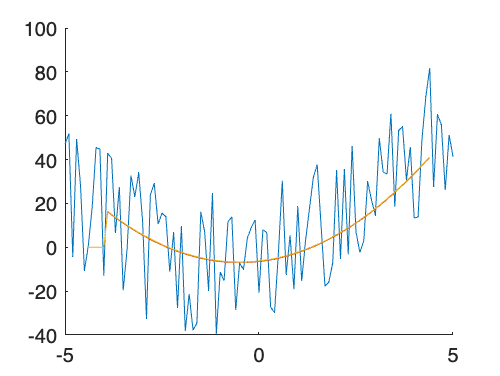


% Plot median and mean over the corrected x
plot(xCorrected,YMedFiltered)
plot(xCorrected,YMeanFiltered)